# Assignment 02 - A.A. 2023/24

close all
clear
clc

## 0) Variables

M1 = 5;     % [kg]
M2 = 4;     % [kg]
M3 = 5;     % [kg]

J2 = 7;     % [kg*m^2]
J3 = 6;     % [kg*m^2]

M4 = 2;     % [kg]
R = 0.8;    % [m]
r = 0.6;    % [m]

k1 = 300;   % [N/m]
k2 = 350;   % [N/m]
k3 = 50;    % [N/m]

c1 = 0.5;   % [N*s/m]
c2 = 2;     % [N*s/m]
c3 = 10;    % [N*s/m]

## 1.A) Equation of Motion and system matrices

Write the equations of motion for small vibrations around the represented configuration considering that the system is in its equilibrium position. 

syms x_1(t) theta_2(t) theta_3(t) F(t)

% Kinetic energy -> mass
M_phisic = diag([M1, M2, J2, M3, J3, M4]);
JacM = [1,0,0;  1,0,0   ;  0,1,0    ;
        1,0,-r  ;   0,0,1   ;   -1,0,r];
M_star = JacM.' * M_phisic * JacM;


% Elastic potential energy -> stiffness
k_phisic = diag([k1,k2,k3]);
JacK = [1,0,0;0,-R,-2*r;-1,0,r];
K_star = JacK.' * k_phisic * JacK;

% Dissipative energy -> damping
c_phisic = diag([c1,c2,c3]);
JacC = JacK;
C_star = JacC.' * c_phisic * JacC;

% Lagrangian of the force
JacF = [1, 0, -r];
Q = JacF.' * F;

% Equations of Motion
x = [x_1; theta_2; theta_3];    % independent variables
dx = diff(x,t,1);               % 1st derivative
ddx = diff(x,t,2);              % 2nd derivative

EoM = M_star*ddx + C_star*dx + K_star*x;
ODESdamped = M_star*ddx + C_star*dx + K_star*x == Q;
ODESundamped = M_star*ddx + K_star*x == Q;

## 1.B) Undamped

[V,D] = eig(-M_star\K_star);            % Eigenvectors and eigenvalues
w_nat = sort(imag(sqrt(diag(D))));      % Natural frequencies

mode_shapes = V ./ V(1, :);         % Normalization to the first row
mode_shapes = [mode_shapes(:, 3), mode_shapes(:, 2), mode_shapes(:, 1)];    % Sorting for increasing w_nat

mode_shapes_1 = mode_shapes(1, :);      % Coefficients for x_1
mode_shapes_2 = mode_shapes(2, :);      % Coefficients for theta_2
mode_shapes_3 = mode_shapes(3, :);      % Coefficients for theta_3

## 1.B) Damped

Evaluate the eigenfrequencies and corresponding eigenvectors in case of undamped and damped system.

% State matrix A
B = [M_star, zeros(size(M_star)); zeros(size(M_star)), M_star];
D = [C_star, K_star; -M_star, zeros(size(M_star))];
A = (-B\D);

[V_damp, D_damp] = eig(A);          % Eigenvectors and eigenvalues
lambda = sort(diag(D_damp));        % Lambda solutions
lambda = lambda(2 : 2 : end);       % Selecting one of the conjugate solutions
alpha = -real(lambda);          % Decaying factors
w_damp = imag(lambda);          % Damped frequencies

mode_shapes_damp = V_damp(4:6, :);  % Modes of x (and not x_dot)
mode_shapes_damp = mode_shapes_damp ./ mode_shapes_damp(1, :);      % Normalization to the first row
mode_shapes_damp = [mode_shapes_damp(:, 5), mode_shapes_damp(:, 3), mode_shapes_damp(:, 1)];    % Sorting and selecting

mode_shapes_damp_1 = mode_shapes_damp(1, :);    % Coefficients for x_1
mode_shapes_damp_2 = mode_shapes_damp(2, :);    % Coefficients for theta_2
mode_shapes_damp_3 = mode_shapes_damp(3, :);    % Coefficients for theta_3

h = alpha ./ w_nat;

## 1.C) Rayleigh damping

Assuming Rayleigh damping, evaluate $\alpha$ and $\beta$ to approximate the generalized damping matrix $\left\lbrack C^* \right\rbrack$ to be of the form $\alpha \left\lbrack M\right\rbrack +\beta \left\lbrack k\right\rbrack$.

% Rayleigh components
ray = [1./(2.* w_nat), w_nat./2]\h;

% Rayleigh damping
C_ray = ray(1) * M_star + ray(2) * K_star;

% Updating eigenvalues and eigenvectors
B = [M_star, zeros(size(M_star)); zeros(size(M_star)), M_star];
D = [C_ray, K_star; -M_star, zeros(size(M_star))];
A = (-B\D);

[V_damp, D_damp] = eig(A);          % Eigenvectors and eigenvalues
lambda = sort(diag(D_damp));        % Lambda solutions
lambda = lambda(2 : 2 : end);       % Selecting one of the conjugate solutions
alpha = -real(lambda);          % Decaying factors
w_damp = imag(lambda);          % Damped frequencies

mode_shapes_damp = V_damp(4:6, :);  % Modes of x (and not x_dot)
mode_shapes_damp = mode_shapes_damp ./ mode_shapes_damp(1, :);      % Normalization to the first row
mode_shapes_damp = [mode_shapes_damp(:, 5), mode_shapes_damp(:, 3), mode_shapes_damp(:, 1)];    % Sorting and selecting

mode_shapes_damp_1 = mode_shapes_damp(1, :);    % Coefficients for x_1
mode_shapes_damp_2 = mode_shapes_damp(2, :);    % Coefficients for theta_2
mode_shapes_damp_3 = mode_shapes_damp(3, :);    % Coefficients for theta_3

h = alpha ./ w_nat;

## 2.A) Free motion responses

Plot and comment the free motion of the system starting from the initial conditions reported in the table, being $x_1$, $\theta_2$, $\theta_3$ the displacement of mass $M_1$, and the rotation of disks 2 and 3 (the initial conditions for generic independent variables can be obtained through kinematic relations).

% Initial conditions
x_1_0 = 0.1;            %[m]
theta_2_0 = pi/12;      %[rad]
theta_3_0 = -pi/12;     %[rad]
v_1_0 = 1;              %[m/s]
w_2_0 = 0.5;            %[rad/s]
w_3_0 = 2;              %[rad/s]

% System
syms C_1 C_2 C_3 Phi_1 Phi_2 Phi_3
C_i = [C_1; C_2; C_3];
Phi_i = [Phi_1; Phi_2; Phi_3];

% Position I.C. equations
eq_cond_x_1     = sum((C_i .* abs(mode_shapes_damp_1).') .* cos(Phi_i + angle(mode_shapes_damp_1).')) == x_1_0;
eq_cond_theta_2 = sum((C_i .* abs(mode_shapes_damp_2).') .* cos(Phi_i + angle(mode_shapes_damp_2).')) == theta_2_0;
eq_cond_theta_3 = sum((C_i .* abs(mode_shapes_damp_3).') .* cos(Phi_i + angle(mode_shapes_damp_3).')) == theta_3_0;

shift = atan (w_damp ./ alpha);   % don't know why

% Velocity I.C. equations
eq_cond_v_1 = sum((C_i .* abs(mode_shapes_damp_1).') .* cos(Phi_i + angle(mode_shapes_damp_1).' - shift)) == - v_1_0;
eq_cond_w_2 = sum((C_i .* abs(mode_shapes_damp_2).') .* cos(Phi_i + angle(mode_shapes_damp_1).' - shift)) == - w_2_0;
eq_cond_w_3 = sum((C_i .* abs(mode_shapes_damp_3).') .* cos(Phi_i + angle(mode_shapes_damp_1).' - shift)) == - w_3_0;

% Solving
eq_bundle = [eq_cond_x_1, eq_cond_theta_2, eq_cond_theta_3, eq_cond_v_1, eq_cond_w_2, eq_cond_w_3];
solution = vpasolve(eq_bundle, [C_1, C_2, C_3, Phi_1, Phi_2, Phi_3]);

% Unknowns
const = [double(solution.C_1), double(solution.C_2), double(solution.C_3)];
phase = [double(solution.Phi_1), double(solution.Phi_2), double(solution.Phi_3)];

% Matrix of amplitude frequency components -> CHECK
abs([const(1)*mode_shapes_damp(:, 1), const(2)*mode_shapes_damp(:, 2), const(3)*mode_shapes_damp(:, 3)])

ans =     0.0870    0.1981    0.9423
    1.6566    0.0465    2.0623
    1.0822    0.0096    3.0362


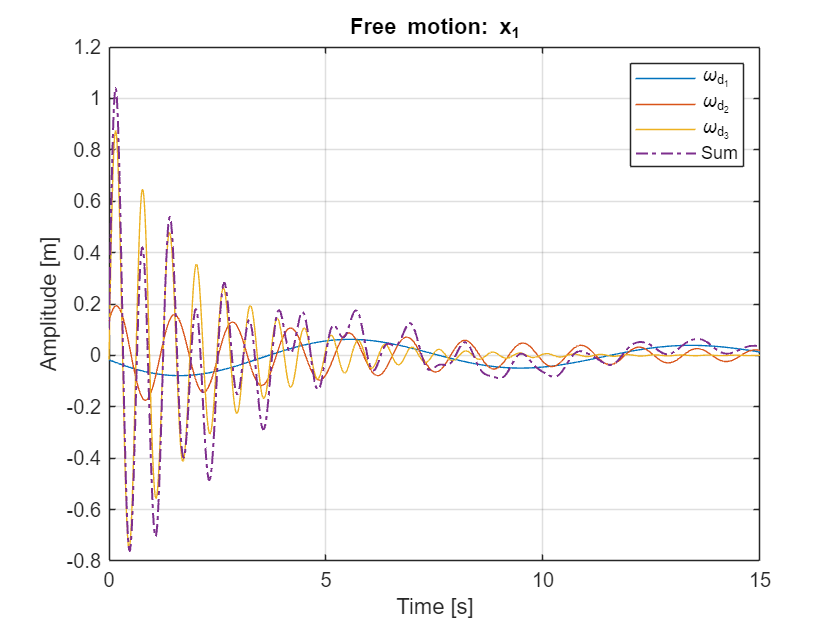

% Plot variables
alfa = alpha.';
omega_d = w_damp.';
%phase = wrapTo2Pi(phase)
t = linspace(0, 70, 70*1e4);

% Plot x_1
x_1 = 0;

% Coefficient for x_1
amplitude = abs(mode_shapes_damp_1);
shift = angle(mode_shapes_damp_1);

figure()

for i = 1:3
    x_1 = x_1 + (exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)))
    hold on;
end

plot(t, x_1, LineWidth = 1, LineStyle = "-.")
titleStr = "Free motion: x_1";
title(titleStr);
grid on;
ylabel("Amplitude [m]");
xlabel("Time [s]");
xlim([0, 15]);
legend("\omega_{d_1}", "\omega_{d_2}", "\omega_{d_3}", "Sum");

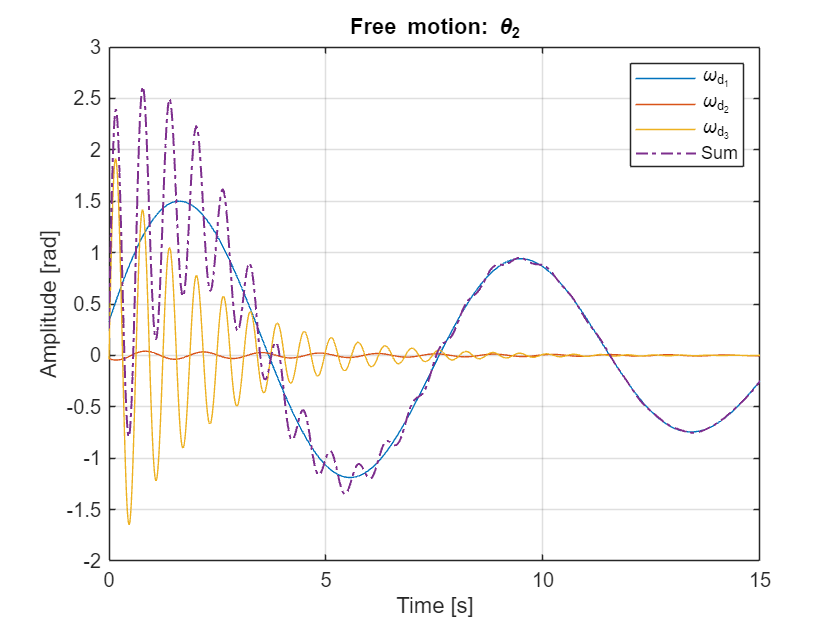

% Plot theta_2
theta_2 = 0;

% Coefficient for theta_2
amplitude = abs(mode_shapes_damp_2);
shift = angle(mode_shapes_damp_2);

figure()

for i = 1:3
    theta_2 = theta_2 + (exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)))
    hold on;
end

plot(t, theta_2, LineWidth = 1, LineStyle = "-.")
titleStr = "Free motion: \theta_2";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("Time [s]");
xlim([0, 15]);
legend("\omega_{d_1}", "\omega_{d_2}", "\omega_{d_3}", "Sum");

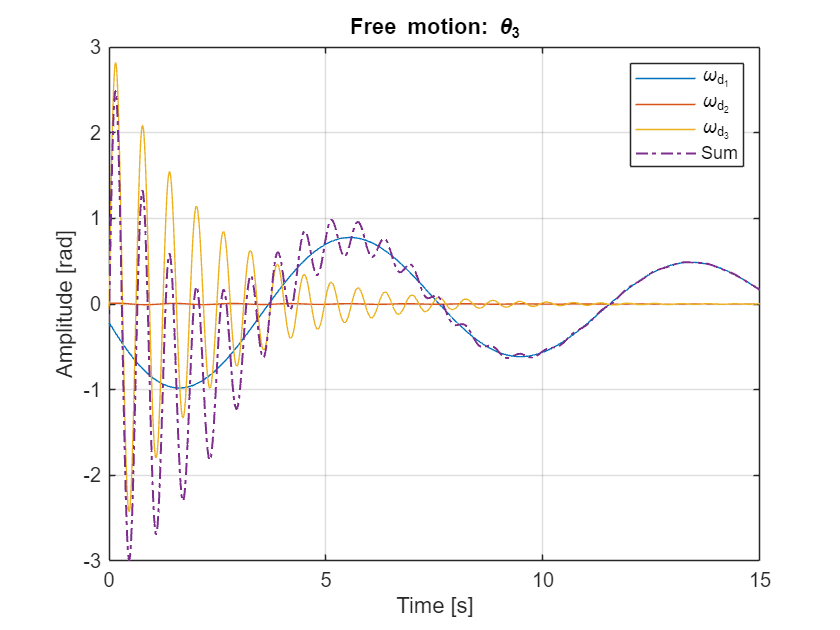

% Plot theta_3
theta_3 = 0;

% Coefficient for theta_3
amplitude = abs(mode_shapes_damp_3);
shift = angle(mode_shapes_damp_3);

figure()

for i = 1:3
    theta_3 = theta_3 + (exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase(i) + shift(i)))
    hold on;
end

plot(t, theta_3, LineWidth = 1, LineStyle = "-.")
titleStr = "Free motion: \theta_3";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("Time [s]");
xlim([0, 15]);
legend("\omega_{d_1}", "\omega_{d_2}", "\omega_{d_3}", "Sum");

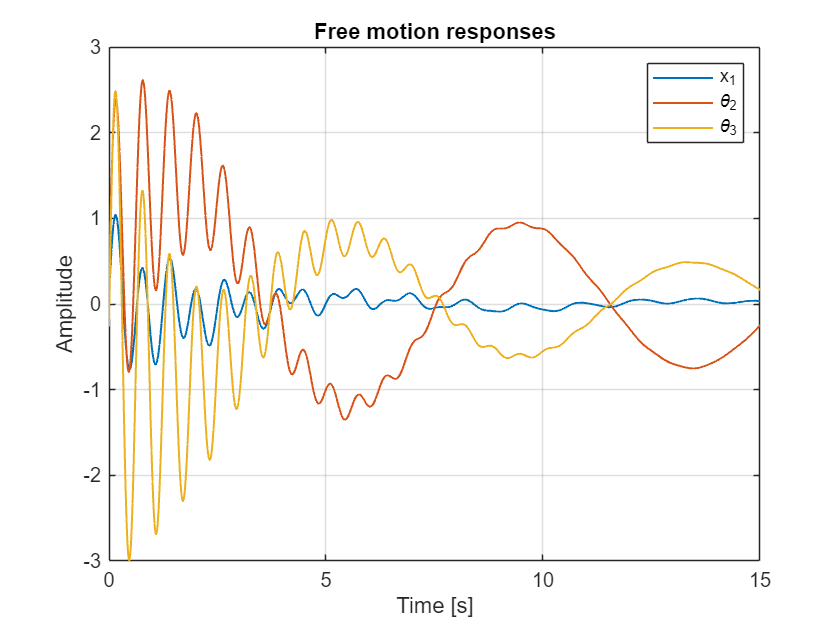

% Plotting together
figure()
plot(t, x_1, LineWidth = 1)
hold on;
plot(t, theta_2, LineWidth = 1)
plot(t, theta_3, LineWidth = 1)
grid on;
titleStr = "Free motion responses";
title(titleStr);
ylabel("Amplitude");
xlabel("Time [s]");
xlim([0, 15]);
legend("x_1", "\theta_2", "\theta_3");

## 2.B) Imposing I.C. - mode 1

Impose particular initial conditions so that only one mode contributes to the free motion of the system.

% Imposing initial conditions -> I.C equal to eigenvector values of w_d_1
x_1_0 = mode_shapes_damp(1, 1);         %[m]
theta_2_0 = mode_shapes_damp(2, 1);     %[rad]
theta_3_0 = mode_shapes_damp(3, 1);     %[rad]
v_1_0 = 0;              %[m/s]
w_2_0 = 0;              %[rad/s]
w_3_0 = 0;              %[rad/s]

% System
syms C_1 C_2 C_3 Phi_1 Phi_2 Phi_3
C_i = [C_1; C_2; C_3];
Phi_i = [Phi_1; Phi_2; Phi_3];

% Position I.C. equations
eq_cond_x_1     = sum((C_i .* abs(mode_shapes_damp_1).') .* cos(Phi_i + angle(mode_shapes_damp_1).')) == x_1_0;
eq_cond_theta_2 = sum((C_i .* abs(mode_shapes_damp_2).') .* cos(Phi_i + angle(mode_shapes_damp_2).')) == theta_2_0;
eq_cond_theta_3 = sum((C_i .* abs(mode_shapes_damp_3).') .* cos(Phi_i + angle(mode_shapes_damp_3).')) == theta_3_0;

shift = atan (w_damp ./ alpha);   % don't know why

% Velocity I.C. equations
eq_cond_v_1 = sum((C_i .* abs(mode_shapes_damp_1).') .* cos(Phi_i + angle(mode_shapes_damp_1).' - shift)) == - v_1_0;
eq_cond_w_2 = sum((C_i .* abs(mode_shapes_damp_2).') .* cos(Phi_i + angle(mode_shapes_damp_1).' - shift)) == - w_2_0;
eq_cond_w_3 = sum((C_i .* abs(mode_shapes_damp_3).') .* cos(Phi_i + angle(mode_shapes_damp_1).' - shift)) == - w_3_0;

% Solving
eq_bundle = [eq_cond_x_1, eq_cond_theta_2, eq_cond_theta_3, eq_cond_v_1, eq_cond_w_2, eq_cond_w_3];
solution = vpasolve(eq_bundle, [C_1, C_2, C_3, Phi_1, Phi_2, Phi_3]);

% Unknowns
%const = [double(solution.C_1), double(solution.C_2), double(solution.C_3)];
const_imp = abs([double(solution.C_1), double(solution.C_2), double(solution.C_3)]);
phase_imp = [double(solution.Phi_1), double(solution.Phi_2), double(solution.Phi_3)];

% Matrix of amplitude frequency components -> CHECK
abs([const_imp(1)*mode_shapes_damp(:, 1), const_imp(2)*mode_shapes_damp(:, 2), const_imp(3)*mode_shapes_damp(:, 3)])

ans =     1.0028    0.0000    0.0000
   19.1004    0.0000    0.0000
   12.4779    0.0000    0.0000


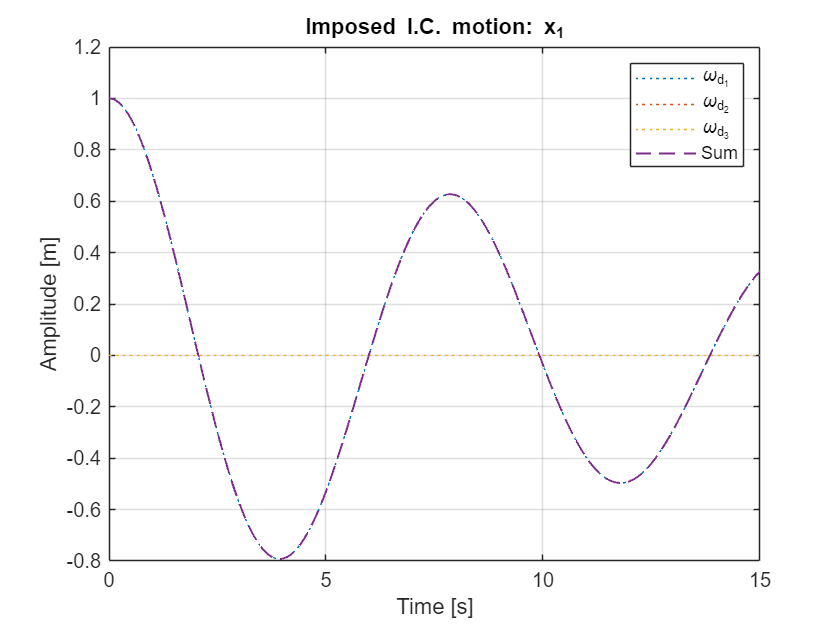

% Plot variables
alfa = alpha.';
omega_d = w_damp.';
%phase = wrapTo2Pi(phase)
max_t = 70; %[s]
dt = 1e-4; %[s]
t = linspace(0, max_t, max_t/dt);

% Plot x_1
x_1_imp = 0;

% Coefficient for x_1
amplitude = abs(mode_shapes_damp_1);
shift = angle(mode_shapes_damp_1);

figure()

for i = 1:3
    x_1_imp = x_1_imp + (exp(-alfa(i) .* t) .* const_imp(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase_imp(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const_imp(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase_imp(i) + shift(i)), LineStyle = ':')
    hold on;
end

plot(t, x_1_imp, LineStyle = "--", LineWidth = 1)
titleStr = "Imposed I.C. motion: x_1";
title(titleStr);
grid on;
ylabel("Amplitude [m]");
xlabel("Time [s]");
xlim([0, 15]);
legend("\omega_{d_1}", "\omega_{d_2}", "\omega_{d_3}", "Sum");

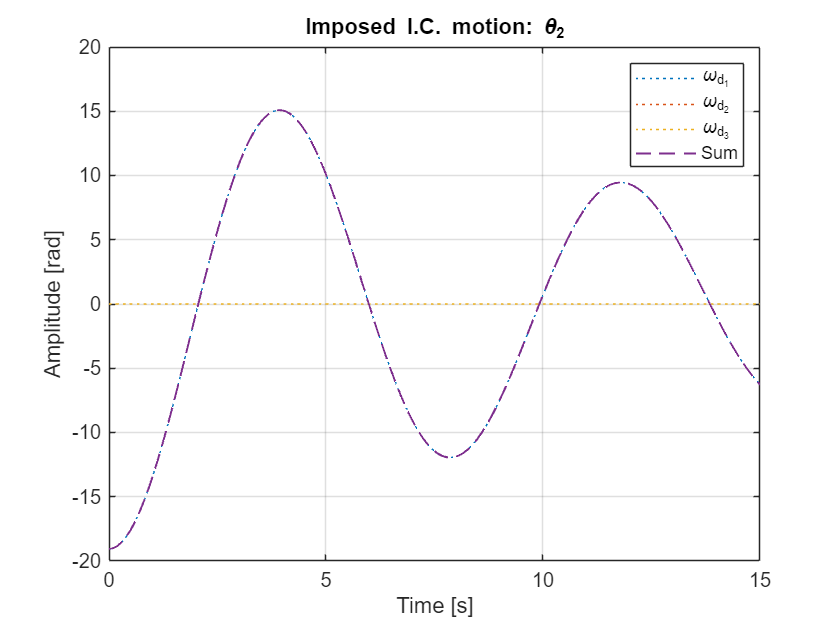

% Plot theta_2
theta_2_imp = 0;

% Coefficient for theta_2
amplitude = abs(mode_shapes_damp_2);
shift = angle(mode_shapes_damp_2);

figure()

for i = 1:3
    theta_2_imp = theta_2_imp + (exp(-alfa(i) .* t) .* const_imp(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase_imp(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const_imp(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase_imp(i) + shift(i)), LineStyle = ':')
    hold on;
end

plot(t, theta_2_imp, LineStyle = "--", LineWidth = 1)
titleStr = "Imposed I.C. motion: \theta_2";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("Time [s]");
xlim([0, 15]);
legend("\omega_{d_1}", "\omega_{d_2}", "\omega_{d_3}", "Sum");

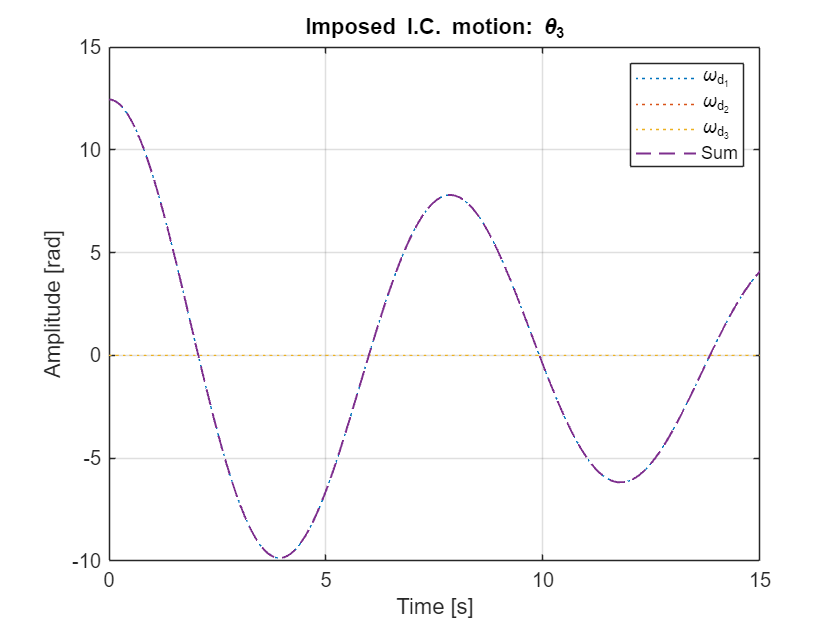

% Plot theta_3
theta_3_imp = 0;

% Coefficient for theta_3
amplitude = abs(mode_shapes_damp_3);
shift = angle(mode_shapes_damp_3);

figure()

for i = 1:3
    theta_3_imp = theta_3_imp + (exp(-alfa(i) .* t) .* const_imp(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase_imp(i) + shift(i)));
    plot(t, exp(-alfa(i) .* t) .* const_imp(i) .* amplitude(i) .* cos(omega_d(i) .* t + phase_imp(i) + shift(i)), LineStyle = ':')
    hold on;
end

plot(t, theta_3_imp, LineStyle = "--", LineWidth = 1)
titleStr = "Imposed I.C. motion: \theta_3";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("Time [s]");
xlim([0, 15]);
legend("\omega_{d_1}", "\omega_{d_2}", "\omega_{d_3}", "Sum");

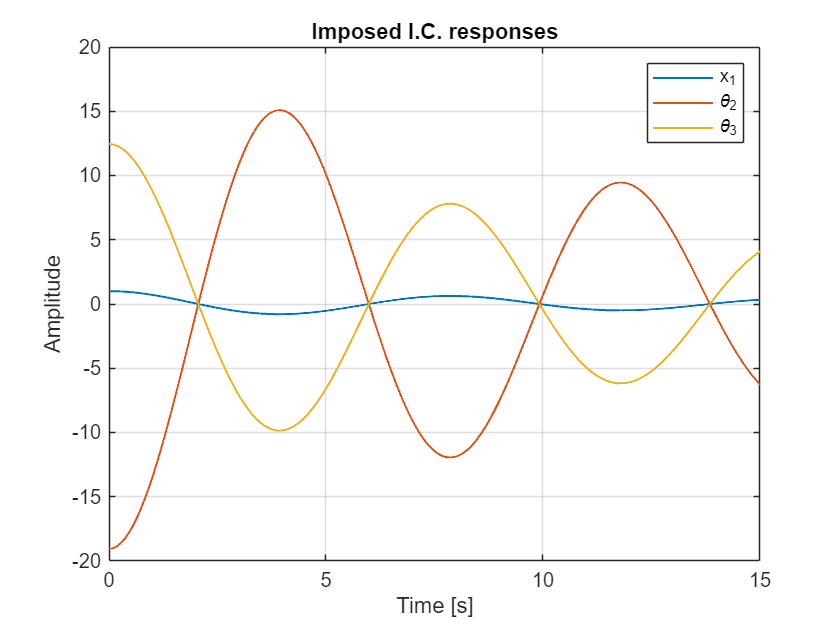

% Plotting together
figure()
plot(t, x_1_imp, LineWidth = 1)
hold on;
plot(t, theta_2_imp, LineWidth = 1)
plot(t, theta_3_imp, LineWidth = 1)
grid on;
titleStr = "Imposed I.C. responses";
title(titleStr);
ylabel("Amplitude");
xlabel("Time [s]");
xlim([0, 15]);
legend("x_1", "\theta_2", "\theta_3");

## 3.A) Frequency response matrix

Plot and comment the elements of the Frequency Response Matrix $H\left(\Omega \right)$.

% Angular frequency axis
W = linspace(0, 15, 15*1e4);

% Frequency response functions
H_11 = zeros(size(W));
H_12 = zeros(size(W));
H_13 = zeros(size(W));
H_21 = zeros(size(W));
H_22 = zeros(size(W));
H_23 = zeros(size(W));
H_31 = zeros(size(W));
H_32 = zeros(size(W));
H_33 = zeros(size(W));

% Frequency response matrix definition
for i = 1:length(W)
    H = inv((-W(i)^2)*M_star + 1i*W(i)*C_ray + K_star);

    % Frequency response functions definition
    H_11(i) = H(1, 1);
    H_12(i) = H(1, 2);
    H_13(i) = H(1, 3);
    H_21(i) = H(2, 1);
    H_22(i) = H(2, 2);
    H_23(i) = H(2, 3);
    H_31(i) = H(3, 1);
    H_32(i) = H(3, 2);
    H_33(i) = H(3, 3);
end

% Clearing H
clear H

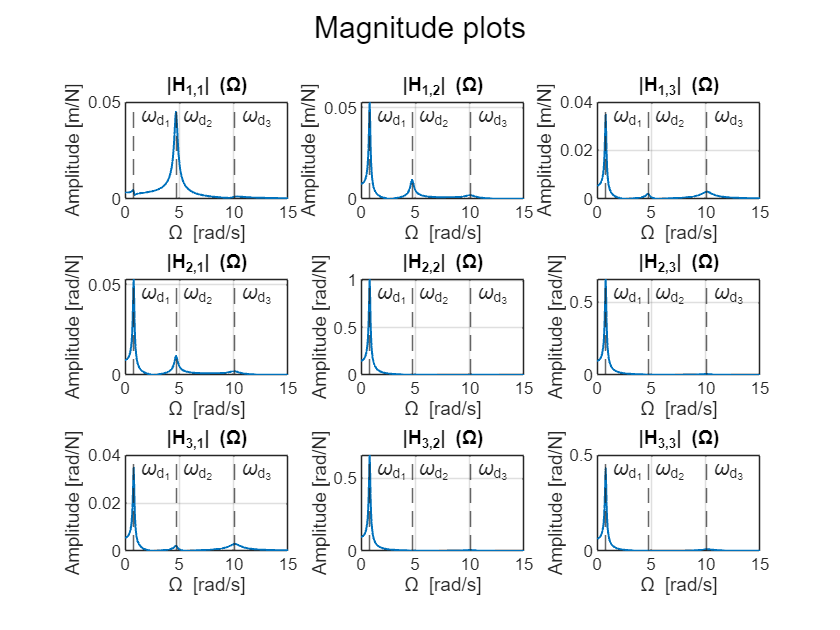

% Amplitude plots
figure()
sgtitle("Magnitude plots");

subplot(3, 3, 1);
plot(W, abs(H_11), LineWidth = 1)
titleStr = "|H_{1,1}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 2);
plot(W, abs(H_12), LineWidth = 1)
titleStr = "|H_{1,2}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 3);
plot(W, abs(H_13), LineWidth = 1)
titleStr = "|H_{1,3}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 4);
plot(W, abs(H_21), LineWidth = 1)
titleStr = "|H_{2,1}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [rad/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 5);
plot(W, abs(H_22), LineWidth = 1)
titleStr = "|H_{2,2}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [rad/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 6);
plot(W, abs(H_23), LineWidth = 1)
titleStr = "|H_{2,3}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [rad/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 7);
plot(W, abs(H_31), LineWidth = 1)
titleStr = "|H_{3,1}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [rad/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 8);
plot(W, abs(H_32), LineWidth = 1)
titleStr = "|H_{3,2}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [rad/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 9);
plot(W, abs(H_33), LineWidth = 1)
titleStr = "|H_{3,3}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [rad/N]");
xlabel("\Omega [rad/s]");

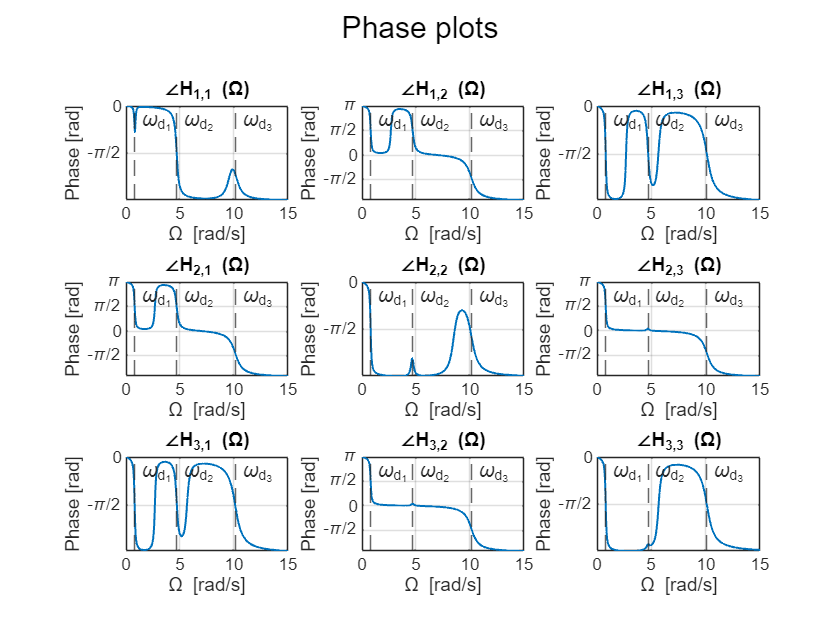

% Phase plots
figure()
sgtitle("Phase plots");

subplot(3, 3, 1);
plot(W, angle(H_11), LineWidth = 1)
titleStr = "\angle{H_{1,1}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 2);
plot(W, angle(H_12), LineWidth = 1)
titleStr = "\angle{H_{1,2}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 3);
plot(W, angle(H_13), LineWidth = 1)
titleStr = "\angle{H_{1,3}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 4);
plot(W, angle(H_21), LineWidth = 1)
titleStr = "\angle{H_{2,1}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 5);
plot(W, angle(H_22), LineWidth = 1)
titleStr = "\angle{H_{2,2}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 6);
plot(W, angle(H_23), LineWidth = 1)
titleStr = "\angle{H_{2,3}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 7);
plot(W, angle(H_31), LineWidth = 1)
titleStr = "\angle{H_{3,1}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 8);
plot(W, angle(H_32), LineWidth = 1)
titleStr = "\angle{H_{3,2}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 9);
plot(W, angle(H_33), LineWidth = 1)
titleStr = "\angle{H_{3,3}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

## 3.B) Co-located FRF for point of force A

Plot the co-located FRF of point A at the centre of the disk 3 (co-located meaning the FRF between the displacement in A and a force applied in A).


$${\textrm{FRF}}_A \left(\Omega \right)=\left\lbrack \begin{array}{ccc}
1 & 0 & -r
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
H_{11}  & H_{12}  & H_{13} \\
H_{21}  & H_{22}  & H_{23} \\
H_{31}  & H_{32}  & H_{33} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & -r
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
H_{13} \\
H_{23} \\
H_{33} 
\end{array}\right\rbrack =H_{13} -r\;H_{33}$$


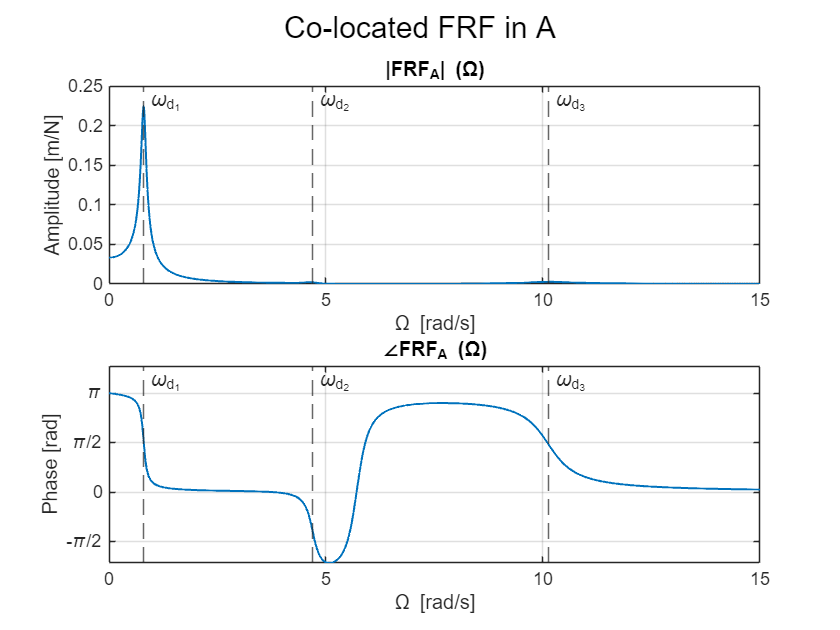

% FRF_A definition
FRF_A = zeros(size(W));

for i = 1:length(W)
    FRF_A(i) = JacF * [H_13(i); H_23(i); H_33(i)];
end

% Plot
figure()
sgtitle("Co-located FRF in A");

subplot(2, 1, 1)
plot(W, abs(FRF_A), LineWidth = 1)
titleStr = "|FRF_{A}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(2, 1, 2)
plot(W, angle(FRF_A), LineWidth = 1)
titleStr = "\angle{FRF_{A}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

## 3.C) Co-located FRF for disk 3

Plot the co-located FRF between the rotation of the disk of radius $r$ and the torque applied onto the disk itself. 


$$H_{33} \left(\Omega \right)=\frac{\Theta_3 }{\;F}=\frac{\Theta_{3\;} }{F\;r}r\Longrightarrow {\textrm{FRF}}_3 =\frac{\Theta_{3\;} }{F\;r}=\frac{H_{33} }{r}=\frac{\Theta_{3\;} }{F\;r}r\;\frac{1}{r}$$


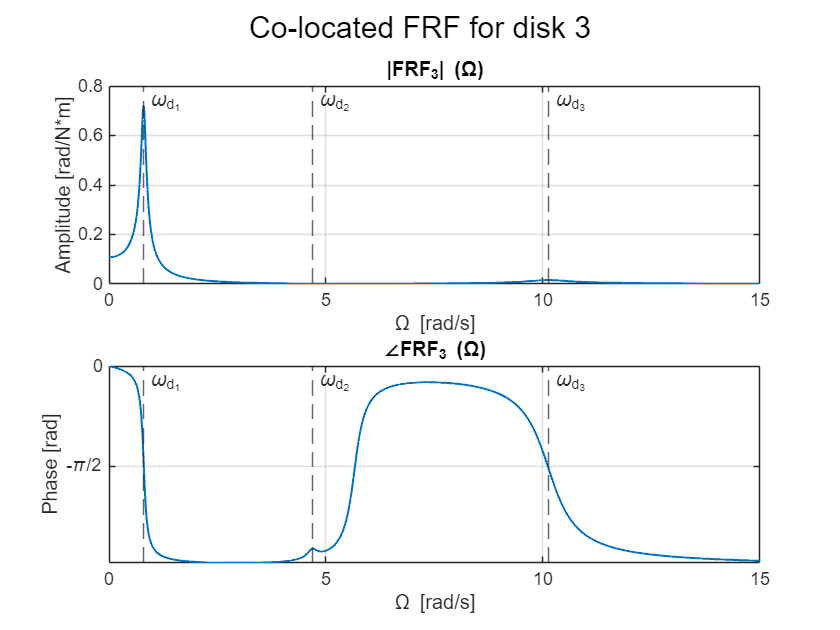

% FRF_3 definition
frf_3 = H_33/r;

% Plots of frf_3
figure()
sgtitle("Co-located FRF for disk 3");

subplot(2, 1, 1)
plot(W, abs(frf_3), LineWidth = 1)
titleStr = "|FRF_{3}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [rad/N*m]");
xlabel("\Omega [rad/s]");

subplot(2, 1, 2)
plot(W, angle(frf_3), LineWidth = 1)
titleStr = "\angle{FRF_{3}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

## 3.D) Harmonic forced response

Starting from the initial condition defined in (2.a), evaluate the complete time response of the system for the three degrees of freedom to the horizontal force in point A, considering that the force is harmonic of the form:


$$F\left(t\right)=F_1 \left(t\right)+F_2 \left(t\right)=A_1 \;\cos \left(2\pi \;f_1 t\right)+A_2 \;\cos \left(2\pi \;f_2 t\right)$$


A_1 = 15;       % [N]
A_2 = 7;        % [N]
f_1 = 0.15;     % [Hz]
f_2 = 0.75;     % [Hz]


$$\underline{\tilde{x_{p_1 } } } \left(t\right)=\underline{{\tilde{X} }_{0_1 } } \;e^{j\;2\pi \;f_1 t} =\left\lbrack \begin{array}{c}
{\tilde{X} }_{1_1 } \\
{\tilde{\Theta} }_{2_1 } \\
{\tilde{\Theta} }_{3_1 } 
\end{array}\right\rbrack e^{j\;2\pi \;f_1 t} =\left\lbrack \begin{array}{ccc}
H_{11}  & H_{12}  & H_{13} \\
H_{21}  & H_{22}  & H_{23} \\
H_{31}  & H_{32}  & H_{33} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
0\\
{\tilde{F} }_1 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
H_{13} \\
H_{23} \\
H_{33} 
\end{array}\right\rbrack \cdot A_1 \;e^{j\;2\pi \;f_1 t} \Longrightarrow \underline{{\tilde{X} }_{0_1 } } =\left\lbrack \begin{array}{c}
{\tilde{X} }_{1_1 } \\
{\tilde{\Theta} }_{2_1 } \\
{\tilde{\Theta} }_{3_1 } 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{c}
H_{13} \\
H_{23} \\
H_{33} 
\end{array}\right\rbrack }_{\Omega =2\pi f_1 } \cdot A_1$$



$$\underline{\tilde{x_{p_2 } } } \left(t\right)=\underline{{\tilde{X} }_{0_2 } } \;e^{j\;2\pi \;f_2 t} =\left\lbrack \begin{array}{c}
{\tilde{X} }_{1_2 } \\
{\tilde{\Theta} }_{2_2 } \\
{\tilde{\Theta} }_{3_2 } 
\end{array}\right\rbrack e^{j\;2\pi \;f_2 t} =\left\lbrack \begin{array}{ccc}
H_{11}  & H_{12}  & H_{13} \\
H_{21}  & H_{22}  & H_{23} \\
H_{31}  & H_{32}  & H_{33} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
0\\
{\tilde{F} }_2 \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
H_{13} \\
H_{23} \\
H_{33} 
\end{array}\right\rbrack \cdot A_2 \;e^{j\;2\pi \;f_2 t} \Longrightarrow \underline{{\tilde{X} }_{0_2 } } =\left\lbrack \begin{array}{c}
{\tilde{X} }_{1_2 } \\
{\tilde{\Theta} }_{2_2 } \\
{\tilde{\Theta} }_{3_2 } 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{c}
H_{13} \\
H_{23} \\
H_{33} 
\end{array}\right\rbrack }_{\Omega =2\pi f_2 } \cdot A_2$$


% Column vectors of H_i3 at f_1 and f_2
h_f1 = [H_13(round(2*pi*f_1*1e4)); H_23(round(2*pi*f_1*1e4)); H_33(round(2*pi*f_1*1e4))];        % FRF_A(2*pi*f_1)
h_f2 = [H_13(round(2*pi*f_2*1e4)); H_23(round(2*pi*f_2*1e4)); H_33(round(2*pi*f_2*1e4))];        % FRF_A(2*pi*f_2)

% Computation of X_01 and X_02 (complex column vectors)
X_01 = h_f1 .* A_1;
X_02 = h_f1 .* A_1;

$\underline{x_{p_1 } } \left(t\right)=\textrm{Re}\left\lbrace \underline{\tilde{x_{p_1 } } } \left(t\right)\right\rbrace =\left\lbrack \begin{array}{c}
|{\tilde{X} }_{1_1 } |\;\cos \left(2\pi \;f_1 t+\angle {\tilde{X} }_{1_1 } \right)\\
|{\tilde{\Theta} }_{2_1 } |\;\cos \left(2\pi \;f_1 t+\angle {\tilde{\Theta} }_{2_1 } \right)\\
|{\tilde{\Theta} }_{3_1 } |\;\cos \left(2\pi \;f_1 t+\angle {\tilde{\Theta} }_{3_1 } \right)
\end{array}\right\rbrack$,                            $\underline{x_{p_2 } } \left(t\right)=\textrm{Re}\left\lbrace \underline{\tilde{x_{p_2 } } } \left(t\right)\right\rbrace =\left\lbrack \begin{array}{c}
|{\tilde{X} }_{1_2 } |\;\cos \left(2\pi \;f_1 t+\angle {\tilde{X} }_{1_2 } \right)\\
|{\tilde{\Theta} }_{2_2 } |\;\cos \left(2\pi \;f_1 t+\angle {\tilde{\Theta} }_{2_2 } \right)\\
|{\tilde{\Theta} }_{3_2 } |\;\cos \left(2\pi \;f_1 t+\angle {\tilde{\Theta} }_{3_2 } \right)
\end{array}\right\rbrack$

% Particular solutions
x_1p = zeros(size(t));
theta_2p = zeros(size(t));
theta_3p = zeros(size(t));

for i = 1:length(t)
    x_1p(i)     = abs(X_01(1))  .* cos(2*pi*f_1*i/1e4 + angle(X_01(1))) + abs(X_02(1)) .* cos(2*pi*f_2*i/1e4 + angle(X_02(1)));
    theta_2p(i) = abs(X_01(2))  .* cos(2*pi*f_1*i/1e4 + angle(X_01(2))) + abs(X_02(2)) .* cos(2*pi*f_2*i/1e4 + angle(X_02(2)));
    theta_3p(i) = abs(X_01(3))  .* cos(2*pi*f_1*i/1e4 + angle(X_01(3))) + abs(X_02(3)) .* cos(2*pi*f_2*i/1e4 + angle(X_02(3)));
end

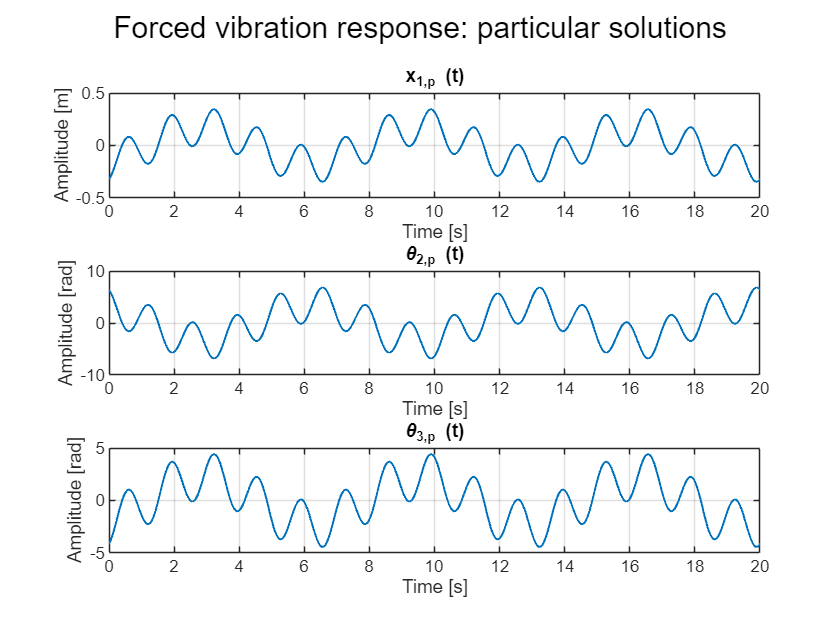

% Forced vibration plots
figure()
sgtitle("Forced vibration response: particular solutions");

subplot(3, 1, 1)
plot(t, x_1p, LineWidth = 1)
titleStr = "x_{1,p} (t)";
title(titleStr);
grid on;
ylabel("Amplitude [m]");
xlabel("Time [s]");
xlim([0, 20]);

subplot(3, 1, 2)
plot(t, theta_2p, LineWidth = 1)
titleStr = "\theta_{2,p} (t)";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("Time [s]");
xlim([0, 20]);

subplot(3, 1, 3)
plot(t, theta_3p, LineWidth = 1)
titleStr = "\theta_{3,p} (t)";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("Time [s]");
xlim([0, 20]);

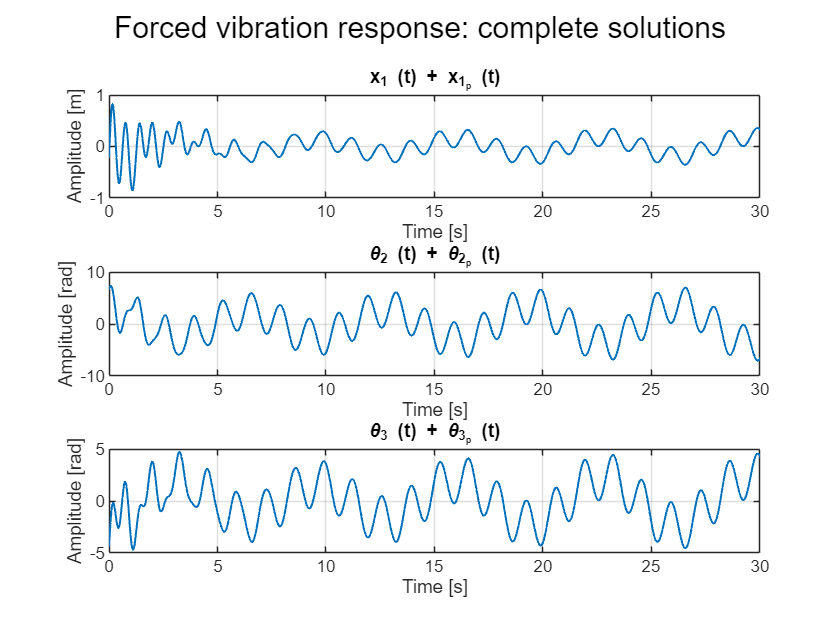


% Complete time response
figure()
sgtitle("Forced vibration response: complete solutions");

subplot(3, 1, 1)
plot(t, x_1p + x_1, LineWidth = 1)
titleStr = "x_1 (t) + x_{1_p} (t)";
title(titleStr);
grid on;
ylabel("Amplitude [m]");
xlabel("Time [s]");
xlim([0, 30]);

subplot(3, 1, 2)
plot(t, theta_2p + theta_2, LineWidth = 1)
titleStr = "\theta_2 (t) + \theta_{2_p} (t)";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("Time [s]");
xlim([0, 30]);

subplot(3, 1, 3)
plot(t, theta_3p + theta_3, LineWidth = 1)
titleStr = "\theta_3 (t) + \theta_{3_p} (t)";
title(titleStr);
grid on;
ylabel("Amplitude [rad]");
xlabel("Time [s]");
xlim([0, 30]);

## 3.E) Triangular wave response


$$F_i \left(t\right)=\frac{8}{\pi^2 }{\left(-1\right)}^i \frac{\sin \left(\left(2i+1\right)\cdot 2\pi f_0 t\right)\;}{{\left(2i+1\right)}^2 }\Longrightarrow F\left(t\right)=\sum_{i=\left\lbrack 0:4\right\rbrack } F_i \left(t\right)$$


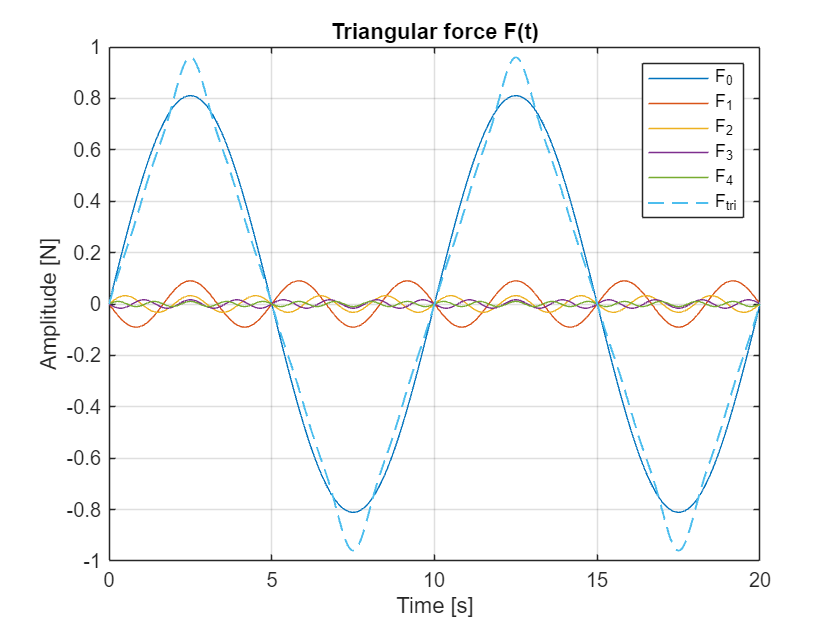

% Fundamental frequency
f_0 = 0.10;     % [Hz]

% Harmonics definition
F_0 = zeros(size(t));
F_1 = zeros(size(t));
F_2 = zeros(size(t));
F_3 = zeros(size(t));
F_4 = zeros(size(t));

for i = 1:length(t)
    F_0(i) = 8/(pi^2) * (-1)^0 * sin((2*0 + 1)*2*pi*f_0*i/1e4)/(2*0 + 1)^2;
    F_1(i) = 8/(pi^2) * (-1)^1 * sin((2*1 + 1)*2*pi*f_0*i/1e4)/(2*1 + 1)^2;
    F_2(i) = 8/(pi^2) * (-1)^2 * sin((2*2 + 1)*2*pi*f_0*i/1e4)/(2*2 + 1)^2;
    F_3(i) = 8/(pi^2) * (-1)^3 * sin((2*3 + 1)*2*pi*f_0*i/1e4)/(2*3 + 1)^2;
    F_4(i) = 8/(pi^2) * (-1)^4 * sin((2*4 + 1)*2*pi*f_0*i/1e4)/(2*4 + 1)^2;
end

% Triangular force definition
F_tri = F_0 + F_1 + F_2 + F_3 + F_4;

% Plot
figure()
plot(t, F_0);
hold on;
plot(t, F_1);
plot(t, F_2);
plot(t, F_3);
plot(t, F_4);
plot(t, F_tri, LineWidth = 1, LineStyle = "--");
titleStr = "Triangular force F(t)";
title(titleStr);
grid on;
ylabel("Amplitude [N]");
xlabel("Time [s]");
legend("F_0", "F_1", "F_2", "F_3", "F_4", "F_{tri}");
xlim([0 2/f_0])

### Steady state solution for $x_3 \left(t\right)$:


$${x_3 }_{{\textrm{ss}}_k } \left(t\right)=|{\textrm{FRF}}_A \left(\Omega =\left(2k+1\right)2\pi f_0 \right)|\frac{8}{\pi^2 }{\left(-1\right)}^k \frac{\sin \left(\left(2k+1\right)\cdot 2\pi f_0 t+\angle \left\lbrack {\textrm{FRF}}_A \left(\Omega =\left(2k+1\right)2\pi f_0 \right)\right\rbrack \right)\;}{{\left(2k+1\right)}^2 }\Longrightarrow x_{3_{\textrm{ss}} } \left(t\right)=\sum_k {x_3 }_{{\textrm{ss}}_k } \left(t\right)$$


% Steady-state solution for theta_2
x_3ss_0 = zeros(size(t));
x_3ss_1 = zeros(size(t));
x_3ss_2 = zeros(size(t));
x_3ss_3 = zeros(size(t));
x_3ss_4 = zeros(size(t));

for i = 1:length(t)
    % Responses to each harmonic component
    x_3ss_0(i) = abs(FRF_A(round((2*0+1)*2*pi*f_0*1e4))) * 8/(pi^2) * (-1)^0 * sin((2*0 + 1)*2*pi*f_0*i/1e4 + angle(FRF_A(round((2*0+1)*2*pi*f_0*1e4))))/(2*0 + 1)^2;
    x_3ss_1(i) = abs(FRF_A(round((2*1+1)*2*pi*f_0*1e4))) * 8/(pi^2) * (-1)^1 * sin((2*1 + 1)*2*pi*f_0*i/1e4 + angle(FRF_A(round((2*1+1)*2*pi*f_0*1e4))))/(2*1 + 1)^2;
    x_3ss_2(i) = abs(FRF_A(round((2*2+1)*2*pi*f_0*1e4))) * 8/(pi^2) * (-1)^2 * sin((2*2 + 1)*2*pi*f_0*i/1e4 + angle(FRF_A(round((2*2+1)*2*pi*f_0*1e4))))/(2*2 + 1)^2;
    x_3ss_3(i) = abs(FRF_A(round((2*3+1)*2*pi*f_0*1e4))) * 8/(pi^2) * (-1)^3 * sin((2*3 + 1)*2*pi*f_0*i/1e4 + angle(FRF_A(round((2*3+1)*2*pi*f_0*1e4))))/(2*3 + 1)^2;
    x_3ss_4(i) = abs(FRF_A(round((2*4+1)*2*pi*f_0*1e4))) * 8/(pi^2) * (-1)^4 * sin((2*4 + 1)*2*pi*f_0*i/1e4 + angle(FRF_A(round((2*4+1)*2*pi*f_0*1e4))))/(2*4 + 1)^2;
end

% Sum of all contributions
x_3ss = x_3ss_0 + x_3ss_1 + x_3ss_2 + x_3ss_3 + x_3ss_4;

% Amplitude contributions
[   abs(FRF_A(round((2*0+1)*2*pi*f_0*1e4)))*((2*0 + 1)^2);
    abs(FRF_A(round((2*1+1)*2*pi*f_0*1e4)))*((2*1 + 1)^2);
    abs(FRF_A(round((2*2+1)*2*pi*f_0*1e4)))*((2*2 + 1)^2);
    abs(FRF_A(round((2*3+1)*2*pi*f_0*1e4)))*((2*3 + 1)^2);
    abs(FRF_A(round((2*4+1)*2*pi*f_0*1e4)))*((2*4 + 1)^2)      ]*8/(pi^2)

ans =     0.0669
    0.0525
    0.0458
    0.0690
    0.0007


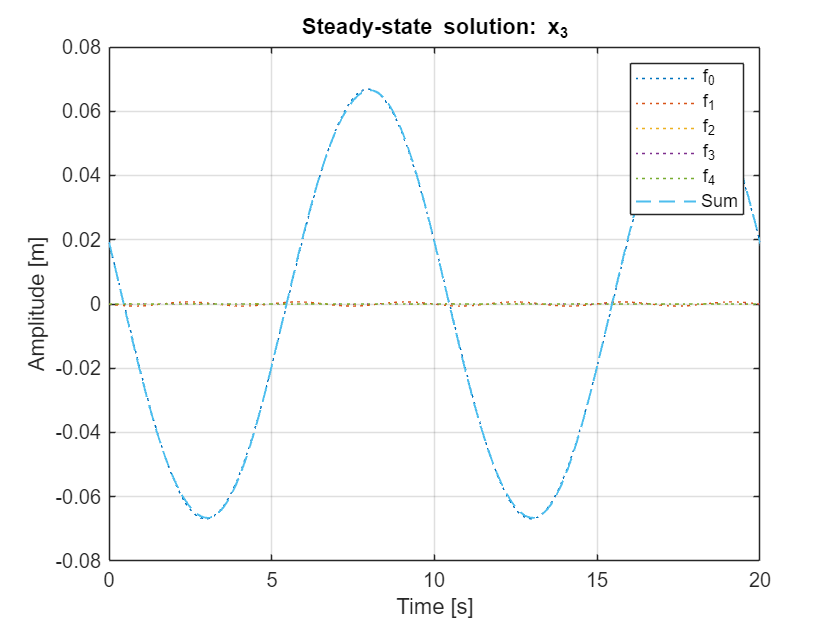


% Plots
figure()
plot(t, x_3ss_0, LineStyle = ":");
hold on;
plot(t, x_3ss_1, LineStyle = ":");
plot(t, x_3ss_2, LineStyle = ":");
plot(t, x_3ss_3, LineStyle = ":");
plot(t, x_3ss_4, LineStyle = ":");
plot(t, x_3ss, LineWidth = 1, LineStyle = '--');
grid on;
titleStr = "Steady-state solution: x_3";
title(titleStr);
ylabel("Amplitude [m]");
xlabel("Time [s]");
legend("f_0", "f_1", "f_2", "f_3", "f_4", "Sum");
xlim([0 2/f_0])

## 4.A) Modal approach

$\left\lbrack \Phi \right\rbrack =\left\lbrack \begin{array}{ccc}
X_{1,U}^{\left(1\right)}  & X_{1,U}^{\left(2\right)}  & X_{1,U}^{\left(3\right)} \\
\Theta_{2,U}^{\left(1\right)}  & {\Theta \;}_{2,U}^{\left(2\right)}  & \Theta_{2,U}^{\left(3\right)} \\
\Theta_{3,U}^{\left(1\right)}  & {\Theta \;}_{3,U}^{\left(2\right)}  & \Theta_{3,U}^{\left(3\right)} 
\end{array}\right\rbrack$,        $\left\lbrack H_q \left(\Omega \right)\right\rbrack ={\left\lbrack -\Omega^2 \left\lbrack M_q \right\rbrack +j\Omega \;\left\lbrack c_q \right\rbrack +\left\lbrack k_q \right\rbrack \right\rbrack }^{-1} =\left\lbrack \begin{array}{ccc}
H_{q_{1,1} } \left(\Omega \right) & 0 & 0\\
0 & H_{q_{2,2} } \left(\Omega \right) & 0\\
0 & 0 & H_{q_{3,3} } \left(\Omega \right)
\end{array}\right\rbrack$

% Phi = mode_shapes
%disp(mode_shapes)

% Modal mass matrix
M_q = mode_shapes.' * M_star * mode_shapes;

% Modal damping matrix
C_q = mode_shapes.' * C_ray * mode_shapes;

% Modal stiffness matrix
K_q = mode_shapes.' * K_star * mode_shapes;

% Clearing all matrices, not purely diagonal matrixes
M_q = diag(diag(M_q));
C_q = diag(diag(C_q));
K_q = diag(diag(K_q));

% Modal FRFs
H_q11 = zeros(size(W));
H_q12 = zeros(size(W));
H_q13 = zeros(size(W));
H_q21 = zeros(size(W));
H_q22 = zeros(size(W));
H_q23 = zeros(size(W));
H_q31 = zeros(size(W));
H_q32 = zeros(size(W));
H_q33 = zeros(size(W));

% Modal FRM
for i = 1:length(W)
    H_q = inv((-W(i)^2)*M_q + 1i*W(i)*C_q + K_q);

    % FRFs entries
    H_q11(i) = H_q(1, 1);
    H_q12(i) = H_q(1, 2);
    H_q13(i) = H_q(1, 3);
    H_q21(i) = H_q(2, 1);
    H_q22(i) = H_q(2, 2);
    H_q23(i) = H_q(2, 3);
    H_q31(i) = H_q(3, 1);
    H_q32(i) = H_q(3, 2);
    H_q33(i) = H_q(3, 3);
end

% Clearing
clear H_q

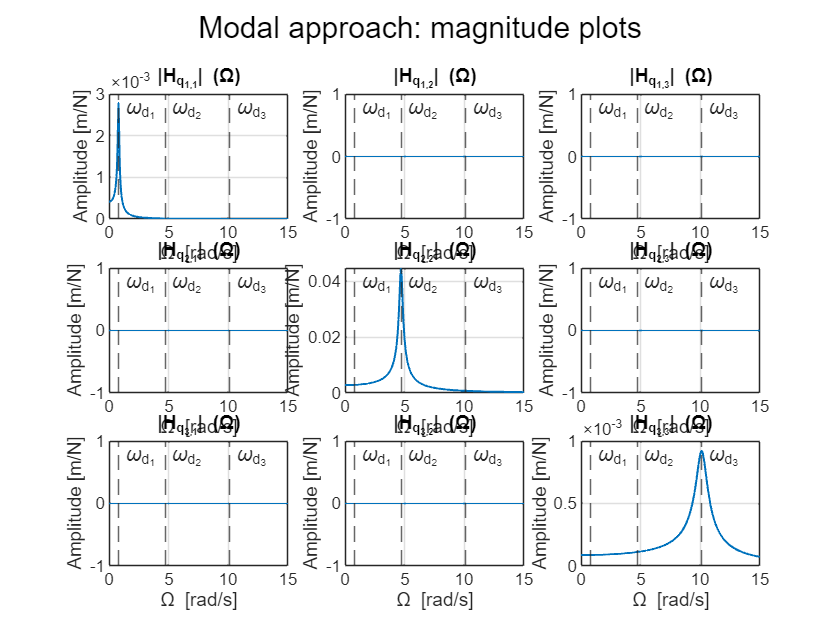

% Amplitude plots
figure()
sgtitle("Modal approach: magnitude plots");

subplot(3, 3, 1);
plot(W, abs(H_q11), LineWidth = 1)
titleStr = "|H_{q_{1,1}}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 2);
plot(W, abs(H_q12), LineWidth = 1)
titleStr = "|H_{q_{1,2}}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 3);
plot(W, abs(H_q13), LineWidth = 1)
titleStr = "|H_{q_{1,3}}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 4);
plot(W, abs(H_q21), LineWidth = 1)
titleStr = "|H_{q_{2,1}}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 5);
plot(W, abs(H_q22), LineWidth = 1)
titleStr = "|H_{q_{2,2}}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 6);
plot(W, abs(H_q23), LineWidth = 1)
titleStr = "|H_{q_{2,3}}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 7);
plot(W, abs(H_q31), LineWidth = 1)
titleStr = "|H_{q_{3,1}}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 8);
plot(W, abs(H_q32), LineWidth = 1)
titleStr = "|H_{q_{3,2}}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 9);
plot(W, abs(H_q33), LineWidth = 1)
titleStr = "|H_{q_{3,3}}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

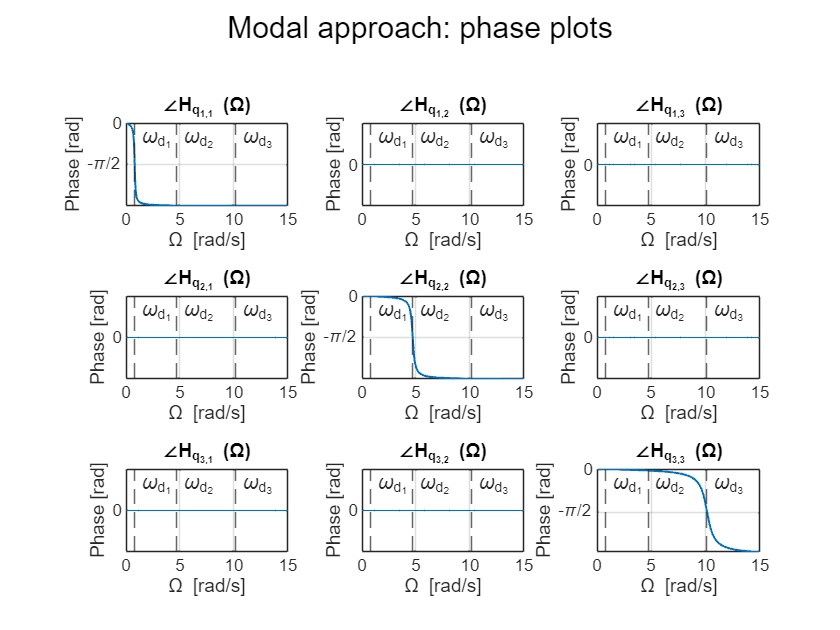

% Phase plots
figure()
sgtitle("Modal approach: phase plots");

subplot(3, 3, 1);
plot(W, angle(H_q11), LineWidth = 1)
titleStr = "\angle{H_{q_{1,1}}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 2);
plot(W, angle(H_q12), LineWidth = 1)
titleStr = "\angle{H_{q_{1,2}}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 3);
plot(W, angle(H_q13), LineWidth = 1)
titleStr = "\angle{H_{q_{1,3}}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 4);
plot(W, angle(H_q21), LineWidth = 1)
titleStr = "\angle{H_{q_{2,1}}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 5);
plot(W, angle(H_q22), LineWidth = 1)
titleStr = "\angle{H_{q_{2,2}}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 6);
plot(W, angle(H_q23), LineWidth = 1)
titleStr = "\angle{H_{q_{2,3}}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 7);
plot(W, angle(H_q31), LineWidth = 1)
titleStr = "\angle{H_{q_{3,1}}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 8);
plot(W, angle(H_q32), LineWidth = 1)
titleStr = "\angle{H_{q_{3,2}}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(3, 3, 9);
plot(W, angle(H_q33), LineWidth = 1)
titleStr = "\angle{H_{q_{3,3}}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

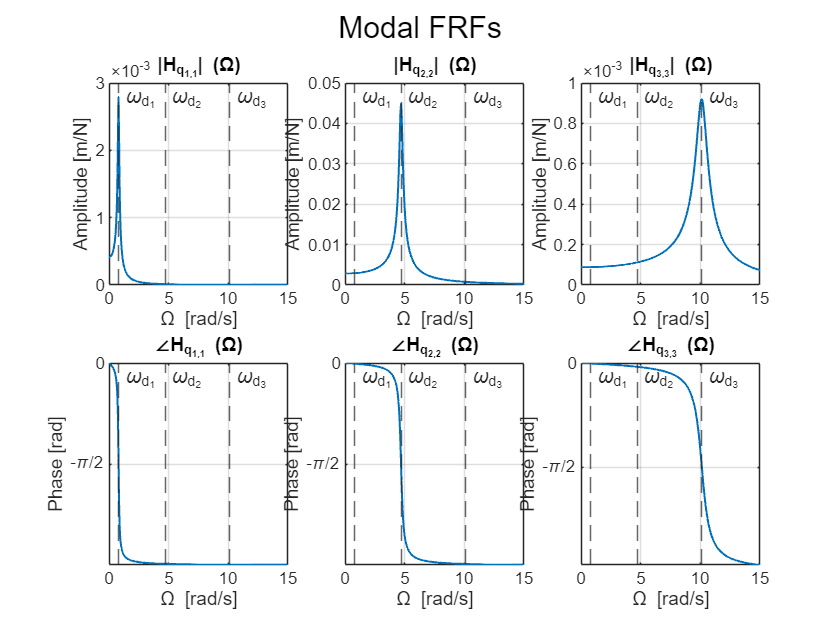

% Plotting all FRFs
figure()
sgtitle("Modal FRFs");

subplot(2, 3, 1);
plot(W, abs(H_q11), LineWidth = 1)
titleStr = "|H_{q_{1,1}}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(2, 3, 2);
plot(W, abs(H_q22), LineWidth = 1)
titleStr = "|H_{q_{2,2}}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(2, 3, 3);
plot(W, abs(H_q33), LineWidth = 1)
titleStr = "|H_{q_{3,3}}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");

subplot(2, 3, 4);
plot(W, angle(H_q11), LineWidth = 1)
titleStr = "\angle{H_{q_{1,1}}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(2, 3, 5);
plot(W, angle(H_q22), LineWidth = 1)
titleStr = "\angle{H_{q_{2,2}}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

subplot(2, 3, 6);
plot(W, angle(H_q33), LineWidth = 1)
titleStr = "\angle{H_{q_{3,3}}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

## 4.B) Modal co-located FRF for point of force A


$${\textrm{FRF}}_A \left(\Omega \right)=H_{13} -r\;H_{33}$$



$$H_{j,k} \left(\Omega \right)=\sum_{i=1,2,3} X_j^{\left(i\right)} X_k^{\left(i\right)} H_{q_{i,i} } \left(\Omega \right)$$


$X_j^{\left(i\right)} ={\left\lbrack \Phi \right\rbrack }_{j,i}$,    $X_k^{\left(i\right)} ={\left\lbrack \Phi \right\rbrack }_{k,i}$

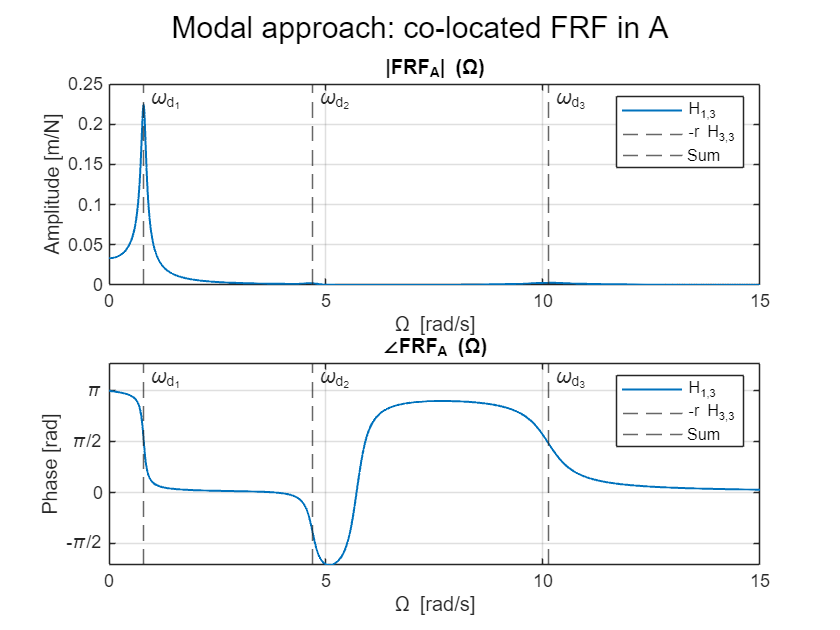

% H_13 and H_33 in modal coordinates
H_13mod = mode_shapes(1, 1) * mode_shapes(3, 1) * H_q11 + mode_shapes(1, 2) * mode_shapes(3, 2) * H_q22 + mode_shapes(1, 3) * mode_shapes(3, 3) * H_q33;
H_33mod = mode_shapes(3, 1) * mode_shapes(3, 1) * H_q11 + mode_shapes(3, 2) * mode_shapes(3, 2) * H_q22 + mode_shapes(3, 3) * mode_shapes(3, 3) * H_q33;

% FRF_A in modal coordinates
FRF_Amod = zeros(size(W));

for i = 1:length(W)
    FRF_Amod(i) = H_13mod(i) - r*H_33mod(i);
end

% Plot
figure()
sgtitle("Modal approach: co-located FRF in A");

subplot(2, 1, 1)
plot(W, abs(FRF_Amod), LineWidth = 1)
titleStr = "|FRF_{A}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [m/N]");
xlabel("\Omega [rad/s]");
legend("H_{1,3}", "-r H_{3,3}", "Sum");

subplot(2, 1, 2)
plot(W, angle(FRF_Amod), LineWidth = 1)
titleStr = "\angle{FRF_{A}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");
legend("H_{1,3}", "-r H_{3,3}", "Sum");

## 4.C) Modal co-located FRF for disk 3


$$H_{33} \left(\Omega \right)=\frac{\Theta_3 }{\;F}=\frac{\Theta_{3\;} }{F\;r}r\Longrightarrow {\textrm{FRF}}_3 =\frac{\Theta_{3\;} }{F\;r}=\frac{H_{33} }{r}=\frac{\Theta_{3\;} }{F\;r}r\;\frac{1}{r}$$


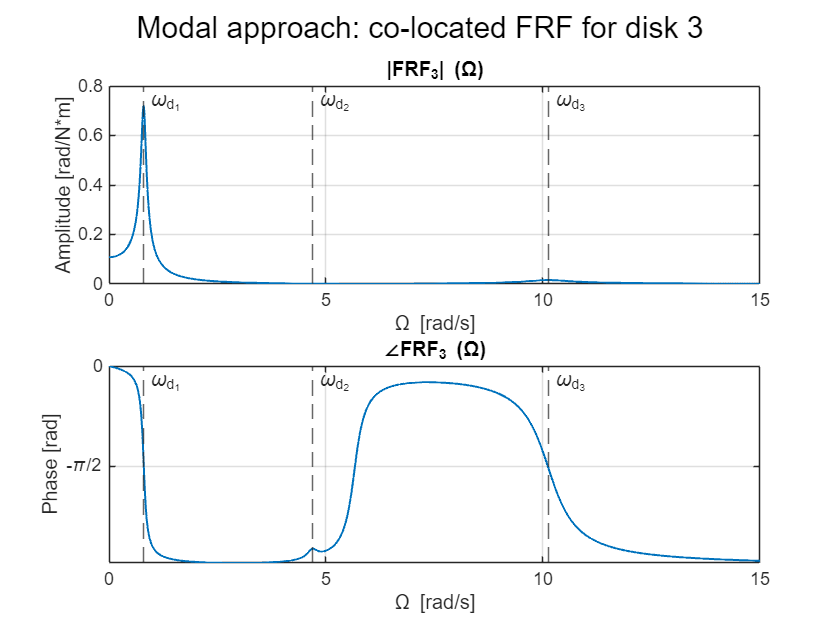

% FRF_3 in modal coordinates
FRF_3mod = H_33mod / r;

% Plot
figure()
sgtitle("Modal approach: co-located FRF for disk 3");

subplot(2, 1, 1)
plot(W, abs(FRF_3mod), LineWidth = 1)
titleStr = "|FRF_{3}| (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
ylabel("Amplitude [rad/N*m]");
xlabel("\Omega [rad/s]");

subplot(2, 1, 2)
plot(W, angle(FRF_3mod), LineWidth = 1)
titleStr = "\angle{FRF_{3}} (\Omega)";
title(titleStr);
grid on;
xline(w_damp(1), LineStyle = "--", Label = "\omega_{d_1}", LabelOrientation = "horizontal");
xline(w_damp(2), LineStyle = "--", Label = "\omega_{d_2}", LabelOrientation = "horizontal");
xline(w_damp(3), LineStyle = "--", Label = "\omega_{d_3}", LabelOrientation = "horizontal");
yticks([-pi, -pi/2, 0, pi/2, pi]);
yticklabels(["-\pi", "-\pi/2", "0", "\pi/2", "\pi"]);
ylabel("Phase [rad]");
xlabel("\Omega [rad/s]");

## 4.D) Forced vibrations

$F\left(t\right)=A_1 \cos \left(2\pi f_1 t\right)\Longrightarrow x_{1_{\textrm{ss}} } \left(t\right)=|H_{1,3} \left(\Omega =2\pi f_1 \right)|\;A_1 \;\cos \left(2\pi \;f_1 t+\angle H_{1,3} \left(\Omega =2\pi f_1 \right)\right)$,    $\theta_{2_{\textrm{ss}} } \left(t\right)=|H_{2,3} \left(\Omega =2\pi f_1 \right)|\;A_1 \;\cos \left(2\pi \;f_1 t+\angle H_{2,3} \left(\Omega =2\pi f_1 \right)\right)$,            $\theta_{3_{\textrm{ss}} } \left(t\right)=|H_{3,3} \left(\Omega =2\pi f_1 \right)|\;A_1 \;\cos \left(2\pi \;f_1 t+\angle H_{3,3} \left(\Omega =2\pi f_1 \right)\right)$

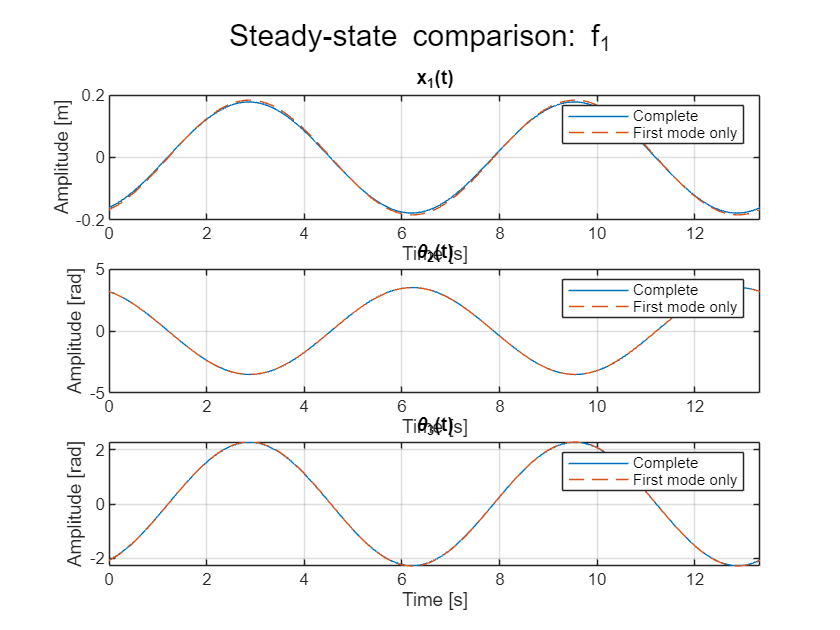

%A_1 = 15;
%f_1 = 0.15;

%H_13mod = mode_shapes(1, 1) * mode_shapes(3, 1) * H_q11 + mode_shapes(1, 2) * mode_shapes(3, 2) * H_q22 + mode_shapes(1, 3) * mode_shapes(3, 3) * H_q33;
%H_33mod = mode_shapes(3, 1) * mode_shapes(3, 1) * H_q11 + mode_shapes(3, 2) * mode_shapes(3, 2) * H_q22 + mode_shapes(3, 3) * mode_shapes(3, 3) * H_q33;

H_23mod = mode_shapes(2, 1) * mode_shapes(3, 1) * H_q11 + mode_shapes(2, 2) * mode_shapes(3, 2) * H_q22 + mode_shapes(2, 3) * mode_shapes(3, 3) * H_q33;

x_1ssmod = zeros(size(t));
theta_2ssmod = zeros(size(t));
theta_3ssmod = zeros(size(t));

for i = 1:length(t)
    x_1ssmod(i) = abs(H_13mod(round(2*pi*f_1*1e4))) * A_1 * cos(2*pi*f_1*i/1e4 + angle(H_13mod(round(2*pi*f_1*1e4))));
    theta_2ssmod(i) = abs(H_23mod(round(2*pi*f_1*1e4))) * A_1 * cos(2*pi*f_1*i/1e4 + angle(H_23mod(round(2*pi*f_1*1e4))));
    theta_3ssmod(i) = abs(H_33mod(round(2*pi*f_1*1e4))) * A_1 * cos(2*pi*f_1*i/1e4 + angle(H_33mod(round(2*pi*f_1*1e4))));
end

% New FRF computation = only first mode contribution
H_13mod = mode_shapes(1, 1) * mode_shapes(3, 1) * H_q11;
H_23mod = mode_shapes(2, 1) * mode_shapes(3, 1) * H_q11;
H_33mod = mode_shapes(3, 1) * mode_shapes(3, 1) * H_q11;

x_1ssvar = zeros(size(t));
theta_2ssvar = zeros(size(t));
theta_3ssvar = zeros(size(t));

for i = 1:length(t)
    x_1ssvar(i) = abs(H_13mod(round(2*pi*f_1*1e4))) * A_1 * cos(2*pi*f_1*i/1e4 + angle(H_13mod(round(2*pi*f_1*1e4))));
    theta_2ssvar(i) = abs(H_23mod(round(2*pi*f_1*1e4))) * A_1 * cos(2*pi*f_1*i/1e4 + angle(H_23mod(round(2*pi*f_1*1e4))));
    theta_3ssvar(i) = abs(H_33mod(round(2*pi*f_1*1e4))) * A_1 * cos(2*pi*f_1*i/1e4 + angle(H_33mod(round(2*pi*f_1*1e4))));
end

% Comparison plots
figure()
sgtitle("Steady-state comparison: f_1")

subplot(3, 1, 1);
plot(t, x_1ssmod);
hold on;
plot(t, x_1ssvar, LineStyle = "--");
grid on;
titleStr = "x_1(t)";
title(titleStr);
ylabel("Amplitude [m]");
xlabel("Time [s]");
legend("Complete", "First mode only");
xlim([0 2/f_1])

subplot(3, 1, 2);
plot(t, theta_2ssmod);
hold on;
plot(t, theta_2ssvar,  LineStyle = "--");
grid on;
titleStr = "\theta_2(t)";
title(titleStr);
ylabel("Amplitude [rad]");
xlabel("Time [s]");
legend("Complete", "First mode only");
xlim([0 2/f_1])

subplot(3, 1, 3);
plot(t, theta_3ssmod);
hold on;
plot(t, theta_3ssvar, LineStyle = "--");
grid on;
titleStr = "\theta_3(t)";
title(titleStr);
ylabel("Amplitude [rad]");
xlabel("Time [s]");
legend("Complete", "First mode only");
xlim([0 2/f_1])

$F\left(t\right)=A_2 \cos \left(2\pi f_2 t\right)\Longrightarrow x_{1_{\textrm{ss}} } \left(t\right)=|H_{1,3} \left(\Omega =2\pi f_2 \right)|\;A_2 \;\cos \left(2\pi \;f_2 t+\angle H_{1,3} \left(\Omega =2\pi f_2 \right)\right)$,    $\theta_{2_{\textrm{ss}} } \left(t\right)=|H_{2,3} \left(\Omega =2\pi f_2 \right)|\;A_2 \;\cos \left(2\pi \;f_2 t+\angle H_{2,3} \left(\Omega =2\pi f_2 \right)\right)$,            $\theta_{3_{\textrm{ss}} } \left(t\right)=|H_{3,3} \left(\Omega =2\pi f_2 \right)|\;A_2 \;\cos \left(2\pi \;f_2 t+\angle H_{3,3} \left(\Omega =2\pi f_2 \right)\right)$

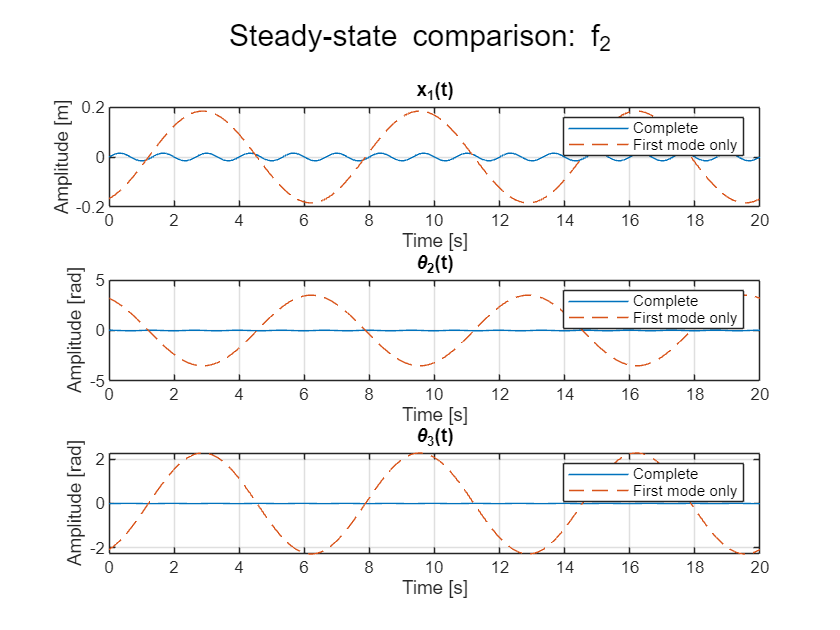

%A_2 = 7;
%f_2 = 0.75;

H_13mod = mode_shapes(1, 1) * mode_shapes(3, 1) * H_q11 + mode_shapes(1, 2) * mode_shapes(3, 2) * H_q22 + mode_shapes(1, 3) * mode_shapes(3, 3) * H_q33;
H_23mod = mode_shapes(2, 1) * mode_shapes(3, 1) * H_q11 + mode_shapes(2, 2) * mode_shapes(3, 2) * H_q22 + mode_shapes(2, 3) * mode_shapes(3, 3) * H_q33;
H_33mod = mode_shapes(3, 1) * mode_shapes(3, 1) * H_q11 + mode_shapes(3, 2) * mode_shapes(3, 2) * H_q22 + mode_shapes(3, 3) * mode_shapes(3, 3) * H_q33;

for i = 1:length(t)
    x_1ssmod(i) = abs(H_13mod(round(2*pi*f_2*1e4))) * A_2 * cos(2*pi*f_2*i/1e4 + angle(H_13mod(round(2*pi*f_2*1e4))));
    theta_2ssmod(i) = abs(H_23mod(round(2*pi*f_2*1e4))) * A_2 * cos(2*pi*f_2*i/1e4 + angle(H_23mod(round(2*pi*f_2*1e4))));
    theta_3ssmod(i) = abs(H_33mod(round(2*pi*f_2*1e4))) * A_2 * cos(2*pi*f_2*i/1e4 + angle(H_33mod(round(2*pi*f_2*1e4))));
end

% New FRF computation = only first mode contribution
H_13mod = mode_shapes(1, 1) * mode_shapes(3, 1) * H_q11;
H_23mod = mode_shapes(2, 1) * mode_shapes(3, 1) * H_q11;
H_33mod = mode_shapes(3, 1) * mode_shapes(3, 1) * H_q11;

x_1ssvar = zeros(size(t));
theta_2ssvar = zeros(size(t));
theta_3ssvar = zeros(size(t));

for i = 1:length(t)
    x_1ssvar(i) = abs(H_13mod(round(2*pi*f_1*1e4))) * A_1 * cos(2*pi*f_1*i/1e4 + angle(H_13mod(round(2*pi*f_1*1e4))));
    theta_2ssvar(i) = abs(H_23mod(round(2*pi*f_1*1e4))) * A_1 * cos(2*pi*f_1*i/1e4 + angle(H_23mod(round(2*pi*f_1*1e4))));
    theta_3ssvar(i) = abs(H_33mod(round(2*pi*f_1*1e4))) * A_1 * cos(2*pi*f_1*i/1e4 + angle(H_33mod(round(2*pi*f_1*1e4))));
end

% Comparison plots
figure()
sgtitle("Steady-state comparison: f_2")

subplot(3, 1, 1);
plot(t, x_1ssmod);
hold on;
plot(t, x_1ssvar, LineStyle = "--");
grid on;
titleStr = "x_1(t)";
title(titleStr);
ylabel("Amplitude [m]");
xlabel("Time [s]");
legend("Complete", "First mode only");
xlim([0 20])

subplot(3, 1, 2);
plot(t, theta_2ssmod);
hold on;
plot(t, theta_2ssvar,  LineStyle = "--");
grid on;
titleStr = "\theta_2(t)";
title(titleStr);
ylabel("Amplitude [rad]");
xlabel("Time [s]");
legend("Complete", "First mode only");
xlim([0 20])

subplot(3, 1, 3);
plot(t, theta_3ssmod);
hold on;
plot(t, theta_3ssvar, LineStyle = "--");
grid on;
titleStr = "\theta_3(t)";
title(titleStr);
ylabel("Amplitude [rad]");
xlabel("Time [s]");
legend("Complete", "First mode only");
xlim([0 20])